# Deep Speech Transfer Learning

Deep Speech was an early and well-performing attempt at "end-to-end" speech recognition [1]. The Deep Speech model was trained on an American English vocabularly of common words using approximately clean speech. In this example, you apply transfer learning to the Deep Speech network to perform speech-to-text with low SNR.

To run the example quickly, set `speedupExample` to `true`. To run the full example as published, set `speedupExample` to `false`.

speedupExample = false;

For reproducibility, set the random seed to `default`.

rng default

## Load Data

This example uses the clean dev set of the LibriSpech Dataset [1] to train and the clean test set for validation and testing. To get better results (at the cost of more training time) consider using the LibriSpeech train sets for training. Download the datasets and unzip the downloaded files.

dataFolder = tempdir;
datasetTrain = fullfile(dataFolder,"LibriSpeech","dev-clean");
if ~isfolder(datasetTrain)
    filename = "dev-clean.tar.gz";
	  url = "http://www.openSLR.org/resources/12/" + filename;
    gunzip(url,dataFolder);
    unzippedFile = fullfile(dataFolder,filename);
    untar(unzippedFile{1}(1:end-3),dataFolder);
end

datasetTest = fullfile(dataFolder,"LibriSpeech","test-clean");
if ~isfolder(datasetTest)
    filename = "test-clean.tar.gz";
	  url = "http://www.openSLR.org/resources/12/" + filename;
    gunzip(url,dataFolder);
    unzippedFile = fullfile(dataFolder,filename);
    untar(unzippedFile{1}(1:end-3),dataFolder);
end

Create datastores to manage the train and validation data sets.

adsTrain = audioDatastore(datasetTrain,IncludeSubfolders=true);
adsTest = audioDatastore(datasetTest,IncludeSubfolders=true);

Get the labels for each file name.

tds = fileDatastore(datasetTrain, ...
    ReadFcn=@(x)readlines(x,EmptyLineRule='skip'), ...
    IncludeSubfolders=true,FileExtensions=".txt");
allLabels = readall(tds);
allLabels = cat(1,allLabels{:});
allLabels = regexp(allLabels,"\s",split="once");
allLabels = cat(1,allLabels{:});
fnLabelOrder = allLabels(:,1);
adsTrain.Labels = replace(lower(allLabels(:,2)),' ','|');

Confirm the labels are in the same order as the corresponding files. Set the labels on the datastore.

[~,fn] = fileparts(adsTrain.Files);
isequal(fn,fnLabelOrder)

ans = logical
   1


Repeat for the test datastore.

tds = fileDatastore(datasetTest, ...
    ReadFcn=@(x)readlines(x,EmptyLineRule='skip'), ...
    IncludeSubfolders=true,FileExtensions=".txt");
allLabels = readall(tds);
allLabels = cat(1,allLabels{:});
allLabels = regexp(allLabels,"\s",split="once");
allLabels = cat(1,allLabels{:});
fnLabelOrder = allLabels(:,1);
adsTest.Labels = replace(lower(allLabels(:,2)),' ','|');

[~,fn] = fileparts(adsTest.Files);
isequal(fn,fnLabelOrder)

ans = logical
   1


Split the test set into validation and test sets.

adsTest = shuffle(adsTest);
N = numel(adsTest.Files);
idx = round(0.8*N);
adsValidation = subset(adsTest,1:idx);
adsTest = subset(adsTest,idx+1:N);

Reduce the size of the datastores if `speedupExample=true`.

if speedupExample
    adsTrain = subset(adsTrain,1:round(0.1*numel(adsTrain.Files)));
    adsValidation = subset(adsValidation,1:round(0.1*numel(adsValidation.Files)));
    adsTest = subset(adsTest,1:round(0.1*numel(adsTest.Files)));
end

Plot a histogram of the file durations in the training set.

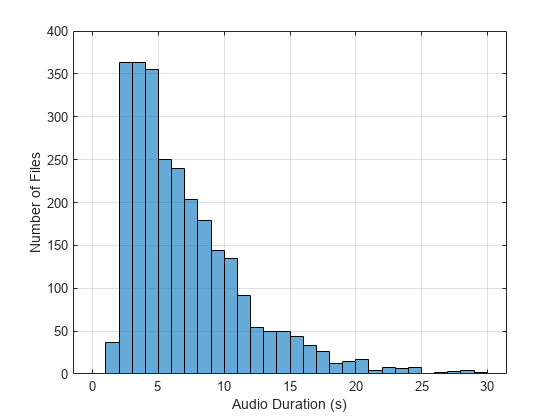

signalLengths = cellfun(@(x)x.Duration,cellfun(@audioinfo,adsTrain.Files,UniformOutput=false),UniformOutput=false);

histogram([signalLengths{:}],0:30)
grid on
xlabel('Audio Duration (s)')
ylabel('Number of Files')

Remove files outside of a min and max duration to reduce the padding in mini-batches.

minDuration = 1;
maxDuration = 18;
idxToRemove = [signalLengths{:}]>maxDuration | [signalLengths{:}]<minDuration;
adsTrain = subset(adsTrain,~idxToRemove);

Sort the files by length.

signalLengths = cellfun(@(x)x.Duration,cellfun(@audioinfo,adsTrain.Files,UniformOutput=false),UniformOutput=false);
signalLengths = [signalLengths{:}];
[signalLengths,idx] = sort(signalLengths);

files = adsTrain.Files;
labels = adsTrain.Labels;
files = files(idx);
labels = labels(idx);
adsTrain = audioDatastore(files);
adsTrain.Labels = labels;

## Load Pretrained Network

Use the `deepspeech` function to load a pretrained Deep Speech network. If you have not already downloaded the network and placed it on path, the function returns an error with a link to the file location.

clear deepspeech
[net,dict] = deepspeech();
net

net =   DAGNetwork with properties:

         Layers: [17×1 nnet.cnn.layer.Layer]
    Connections: [16×2 table]
     InputNames: {'input'}
    OutputNames: {'classOutput'}


The Deep Speech network is returned a `DAGNetwork` object. To perform transfer learning, you need to use the CTC loss function, which is more suitable to a custom (`dlnetwork`-based) training loop. To convert the `DAGNetwork` to a `dlnetwork`, first create a layer graph from the network, then remove the final classification layer from the layer graph, and then convert the layer graph to a `dlnetwork`.

lg = layerGraph(net);
lg = removeLayers(lg,"classOutput");
net = dlnetwork(lg)

net =   dlnetwork with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
    Connections: [15×2 table]
     Learnables: [13×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


The second argument output from `deepspeech` is the dictionary necessary to decode Deep Speech output. The dictionary corresponds to the dictionary used to train Deep Speech.

dict

dict = 1×29 cell array
    {' '}    {'a'}    {'b'}    {'c'}    {'d'}    {'e'}    {'f'}    {'g'}    {'h'}    {'i'}    {'j'}    {'k'}    {'l'}    {'m'}    {'n'}    {'o'}    {'p'}    {'q'}    {'r'}    {'s'}    {'t'}    {'u'}    {'v'}    {'w'}    {'x'}    {'y'}    {'z'}    {'''}    {'<blank>'}


dict{1} = '|';
dict = dictionary(string(dict),1:numel(dict));
deepspeech.Dictionary = dict;

## Evaluate Deep Speech Performance

Spot-check Deep Speech performance on the test set.

Read an audio file from the datastore and listen to it.

[audioIn,audioInfo] = read(adsTest);
fs = audioInfo.SampleRate;

sound(audioIn,fs)

Pass the audio signal through the `deepspeechFeatures` function to extract features.

x = deepspeechFeatures(audioIn,fs);

Pass the features through the `deepspeechBuffer` function to buffer features. The output from `deepspeechBuffer` is a C-by-T array, where C is the channel dimension and T is the time dimension.

xb = deepspeechBuffer(x);

Pass the buffered features through the network to return an array of dictionary element probabilities. The `dlnetwork` requires the input to be a formatted dlarray.

y = predict(net,dlarray(xb,"CT"));

Pass the prediction through `deepspeechPostprocess` to convert the probabilities to text. The `deepspeechPostprocess` function requires the input to be a regular C-by-T array. Extract the data from the `dlarray` before calling the `deepspeechPostprocess` function.

textPrediction = deepspeechPostprocess(extractdata(y))

textPrediction = 'for general service therefore requiring no special effort the numerical strength of the factions was about equal one on extra ordinary occasions the two thousand borderoffian reserve lying a little farther back from the state line could at any time easily turn the scale'

Display the known, ground-truth, text.

textKnown = replace(string(audioInfo.Label),"|"," ")

textKnown = "for general service therefore requiring no special effort the numerical strength of the factions was about equal while on extraordinary occasions the two thousand border ruffian reserve lying a little farther back from the state line could at any time easily turn the scale"

Calcuate the word-error rate of the entire test data set. This functionality requires Text Analytics Toolbox™.

wordErrorRate(net,adsTest,CorrectSpelling=true)

Word error rate = 0.12859


## Augment Data Set

Add noise to the data sets at a specific SNR to better reflect the target application of transfer learning.

Load a noise file similar to the target application background noise. Resample it to the sample rate of the training data set.

[noise,noiseFs] = audioread("WashingMachine-16-8-mono-1000secs.mp3");
noise = resample(noise,fs,noiseFs);

Read from the test datastore. Use the supporting function, `mixSNR`, to mix the audio with the noise at the desired SNR.

[audioIn,audioInfo] = read(adsTest);
desiredSNR = 0; % dB
audioIn = mixSNR(audioIn,noise,desiredSNR);

Listen to the noisy signal.

sound(audioIn,audioInfo.SampleRate)

Pass the noisy audio through the Deep Speech system to predict text.

x = deepspeechFeatures(audioIn,audioInfo.SampleRate);
xb = deepspeechBuffer(x);
y = predict(net,dlarray(xb,"CT"));
textPrediction = deepspeechPostprocess(extractdata(y))

textPrediction = 'vigeneal service therefore requiring nopecial epe the numerical stregt of the factions was bout one on etrabordinary casion the two thousand border rupingreserved lying ab parther backated by'

Display the known, ground-truth, text.

textKnown = string(audioInfo.Label)

textKnown = "for|general|service|therefore|requiring|no|special|effort|the|numerical|strength|of|the|factions|was|about|equal|while|on|extraordinary|occasions|the|two|thousand|border|ruffian|reserve|lying|a|little|farther|back|from|the|state|line|could|at|any|time|easily|turn|the|scale"

### Add Noise to Data Set

Create transformed training and validation datastores that apply noise to the audio signal upon reading.

tdsTrain = transform(@(x)mixSNR(x,noise,desiredSNR),adsTrain);
tdsValidation = transform(@(x)mixSNR(x,noise,desiredSNR),adsValidation);
tdsTest = transform(@(x)mixSNR(x,noise,desiredSNR),adsTest);

Calculate the word error rate for the augmented validation data set.

wordErrorRate(net,tdsTest,CorrectSpelling=true)

Word error rate = 0.62964


## Prepare Data for CTC-Based Training

The network will learn to recognize elements in the dictionary.

First, create a map between the dictionary and the network output. The dictionary is in the same order as the network output.

dict = deepspeech.Dictionary;

Convert the labels on the datastore to `char` arrays.

trainLabels = cellstr(adsTrain.Labels);
validationLabels = cellstr(adsValidation.Labels);
testLabels = cellstr(adsTest.Labels);

Convert the `char` arrays to arrays of the corresponding values.

trainLabels = cellfun(@(L)dict(split(string(L'))),trainLabels,UniformOutput=false);
validationLabels = cellfun(@(L)dict(split(string(L'))),validationLabels,UniformOutput=false);
testLabels = cellfun(@(L)dict(split(string(L'))),testLabels,UniformOutput=false);

Create combined datastores so that the first element output is the audio signal, and the second element output is the encoded label.

dsTrain = combine(tdsTrain,arrayDatastore(trainLabels,OutputType="same"));
dsValidation = combine(tdsValidation,arrayDatastore(validationLabels,OutputType="same"));
dsTest = combine(tdsTest,arrayDatastore(testLabels,OutputType="same"));

Sanity check the encoding by doing a reverse lookup.

reverseLookup = containers.Map(dict.values,dict.keys);

previewValidation = preview(dsTrain);
audioData = preview(dsTrain.UnderlyingDatastores{1});
label = previewValidation{2};
stringLabel = reverseLookup.values(num2cell(label));
stringLabel = join(string(stringLabel(:)'),'')

stringLabel = "yes"

sound(audioData,16e3)

## Specify Training Options

Specify the number of epochs to train for and the mini-batch size.

numEpochs = 7;
miniBatchSize = 16;

Use the Adam solver for training. Specify parameters of the `adamupdate` fuction.

learnRate = 1e-4;
learnRateDropPeriod = 5;
learnRateDropFactor = 0.1;
gradDecay = 0.9;
sqGradDecay = 0.999;
averageGrad = [];
averageSqGrad = [];

Define which layers you allow to learn. Deep Speech consists of fully-connected layers, an LSTM layer, and more fully-connected layers.

analyzeNetwork(net)

In transfer learning, you will generally only allow the last few layers to learn. In this example, you allow the first few layers to learn. This is because you are helping the feature extraction learn to deal with noise.

net.Learnables

ans = 13×3 table
    Layer         Parameter                Value       
    ______    __________________    ___________________

    "fc1"     "Weights"             {2048×494  dlarray}
    "fc1"     "Bias"                {2048×1    dlarray}
    "fc2"     "Weights"             {2048×2048 dlarray}
    "fc2"     "Bias"                {2048×1    dlarray}
    "fc3"     "Weights"             {2048×2048 dlarray}
    "fc3"     "Bias"                {2048×1    dlarray}
    "lstm"    "InputWeights"        {8192×2048 dlarray}
    "lstm"    "RecurrentWeights"    {8192×2048 dlarray}
    "lstm"    "Bias"                {8192×1    dlarray}
    "fc4"     "Weights"             {2048×2048 dlarray}
    "fc4"     "Bias"                {2048×1    dlarray}
    "fc5"     "Weights"             {  29×2048 dlarray}
    "fc5"     "Bias"                {  29×1    dlarray}


updatedParamsIdx = 1:6;

## Create Mini-Batch Queue

If you have access to Parallel Computing Toolbox™, set `canUsePCT` to `true` to speed up training.

if canUseParallelPool
    canUsePCT = true;
    gcp;
end

Create `minibatchqueue` objects to manage the input pipeline for the training loop. Use the `deespeechTrainPreprocess` supporting function to pad feature and label inputs to consistent lengths and to create masks indicating the padding.

mbqTrain = minibatchqueue(dsTrain,4, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@(data,labels)deepspeechTrainPreprocess(data,labels), ...
    OutputCast=["single","single","logical","logical"], ...
    OutputAsDlarray=[1,1,1,1], ...
    MiniBatchFormat=["CTB","BT","CBT","BT"], ...
    DispatchInBackground=canUsePCT, ...
    OutputEnvironment="auto", ...
    PartialMiniBatch="discard");
mbqValidation = minibatchqueue(dsValidation,4, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@(data,labels)deepspeechTrainPreprocess(data,labels), ...
    OutputCast=["single","single","logical","logical"], ...
    OutputAsDlarray=[1,1,1,1], ...
    MiniBatchFormat=["CTB","BT","CBT","BT"], ...
    DispatchInBackground=canUsePCT, ...
    OutputEnvironment="auto", ...
    PartialMiniBatch="discard");

## Train Network

Initialize a figure to track the training progress.

lossPlot = figure;
lineLossTrain = animatedline(Color=[0.85 0.325 0.098]);
lineLossMvAvgTrain = animatedline(Color=[0 0.4470 0.7410],LineWidth=2.5,LineStyle="--");
lineLossValidation = animatedline(Color="k",LineStyle="--",Marker="o");
legend(["Train","Smoothed Train","Validation"],AutoUpdate="off",Location="northeast")
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

Run the training loop.

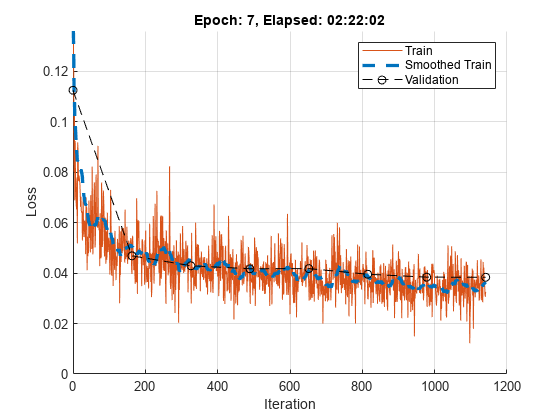

iteration = 0;
start = tic;
% Loop over epochs
for epoch = 1:numEpochs

    % Validation accuracy plot ----------------------------
    reset(mbqValidation)

    lossValidation = [];
    while hasdata(mbqValidation)

        % Read mini-batch of data, targets, and masks
        [X,T,XMask,TMask] = next(mbqValidation);

        % Run the forward pass through the network
        Y = predict(net,X);

        % Find the CTC loss from the network output
        loss = ctc(Y,T,XMask,TMask,BlankIndex=deepspeech.Dictionary("<blank>"));
        loss = loss/sum(TMask,'all');

        % Gather the loss data into a double value
        lossValidation(end+1) = double(gather(extractdata(loss))); %#ok<SAGROW> 
    end
    lossValidation = mean(lossValidation);
    addpoints(lineLossValidation,iteration,lossValidation)
    % ------------------------------------------------------

    % Reset data. Don't shuffle to reduce padding.
    reset(mbqTrain)

    % Loop over mini-batches.
    while hasdata(mbqTrain)
        iteration = iteration + 1;

        % Read mini-batch of data, targets, and masks
        [X,T,XMask,TMask] = next(mbqTrain);

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [loss,gradients] = dlfeval(@deepspeechLoss,net,updatedParamsIdx, ...
            X,T,XMask,TMask,deepspeech.Dictionary("<blank>"));

        % Update the network parameters using the ADAM optimizer.
        [net.Learnables(updatedParamsIdx,:),averageGrad,averageSqGrad] = ...
            adamupdate(net.Learnables(updatedParamsIdx,:),gradients, ...
            averageGrad,averageSqGrad,iteration,learnRate,gradDecay,sqGradDecay);

        % Display the training progress.
        D = duration(0,0,toc(start),Format="hh:mm:ss");

        % Loss line
        addpoints(lineLossTrain,iteration,loss)

        % Moving loss line
        [~, lossVals] = getpoints(lineLossTrain);
        lossMvAvg = movmean(lossVals,50);
        addpoints(lineLossMvAvgTrain,iteration,lossMvAvg(end))

        % Title
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
    if ~rem(epoch,learnRateDropPeriod)
        learnRate = learnRate*learnRateDropFactor;
    end
end

% Final validation accuracy plot
reset(mbqValidation)
lossValidation = [];
while hasdata(mbqValidation)
    [X,T,XMask,TMask] = next(mbqValidation);
    Y = predict(net,X);
    loss = ctc(Y,T,XMask,TMask,BlankIndex=deepspeech.Dictionary("<blank>"));
    loss = loss/sum(TMask,'all');
    lossValidation(end+1) = double(gather(extractdata(loss))); %#ok<SAGROW> 
end
lossValidation = mean(lossValidation);
addpoints(lineLossValidation,iteration,lossValidation)

## Test Network

Evaluate word error rate on the updated network.

wordErrorRate(net,tdsTest,CorrectSpelling=true)

Word error rate = 0.37007


Spot-check network performance.

tdsValidation = shuffle(tdsValidation);
[audioIn,audioInfo] = read(tdsValidation);
sound(audioIn,audioInfo.SampleRate)

x = deepspeechFeatures(audioIn,audioInfo.SampleRate);
xb = deepspeechBuffer(x);
y = predict(net,gpuArray(dlarray(xb,"CTB")));

text = replace(char(audioInfo.Label),'|',' ')

text = 'from time to time a fleecy tuft of mist with yet some gleaming light left upon it drops down upon the dense floor of grey and loses itself in the opaque and impenetrable mass'

textPrediction = deepspeechPostprocess(extractdata(y))

textPrediction = 'from time to time a fity touft of minic wi yet som gleaming lihe buf dupon it prostown upon the dence forof grin and lose fitsilf o in the ovan and a anaterima'

# Supporting Functions

### Mix Signal and Noise At Prescribed SNR

function noisySignal = mixSNR(signal,noise,ratio,nvargs)
%mixSNR Mix signal and noise at prescribed SNR
% noisySignal = mixSNR(signal,noise,ratio) returns a noisy version of the
% signal, noisySignal. The noisy signal has been mixed with noise at the
% specificied ratio in dB.
%
% Copyright 2018-2023 The MathWorks, Inc.

arguments
    signal
    noise
    ratio
    nvargs.Scale = true;
end

numSamples = size(signal,1);

% Convert noise to mono
noise = mean(noise,2);

% Trim or expand noise to match signal size
if size(noise,1)>=numSamples
    % Choose a random starting index such that you still have numSamples
    % after indexing the noise.
    start = randi(size(noise,1) - numSamples + 1);
    noise = noise(start:start+numSamples-1);
else
    numReps = ceil(numSamples/size(noise,1));
    temp = repmat(noise,numReps,1);
    start = randi(size(temp,1) - numSamples - 1);
    noise = temp(start:start+numSamples-1);
end

signalNorm = norm(signal);

noiseNorm = norm(noise);

goalNoiseNorm = signalNorm/(10^(ratio/20));
factor = goalNoiseNorm/noiseNorm;

requestedNoise = noise.*factor;
noisySignal = signal + requestedNoise;

if nvargs.Scale
    scaleFactor = max(abs(noisySignal(:)));
    noisySignal = noisySignal./scaleFactor;
end
end

### Word Error Rate (WER)

function varargout = wordErrorRate(net,ds,nvargs)
%wordErrorRate Word error rate (WER)
% wordErrorRate(net,ds) calculates the word error rate over all files in
% the datastore. Specify ds as an audioDatastore with labels.
%
% wordErrorRate(net,ds,CorrectSpelling=TF) passes the predicted text
% through the correctSpellings function in Text Analytics Toolbox(TM)
% before calculating edit distance. CorrectSpelling defaults to false.
%
% Copyright 2022-2023 The MathWorks, Inc.

arguments
    net
    ds
    nvargs.CorrectSpelling = false;
end

editDistanceTotal = 0;
numWordsTotal = 0;
reset(ds)
while hasdata(ds)
    [audioIn,audioInfo] = read(ds);
    text = replace(char(audioInfo.Label),'|',' ');

    x = deepspeechFeatures(audioIn,audioInfo.SampleRate);
    xb = deepspeechBuffer(x);
    
    xbdl = dlarray(xb,"CTB");
    if canUseGPU
        xbdl = gpuArray(xbdl);
    end
    y = predict(net,xbdl);

    textPrediction = deepspeechPostprocess(extractdata(y));

    tokenizedTextPrediction = tokenizedDocument(textPrediction);
    if nvargs.CorrectSpelling
        tokenizedTextPrediction = correctSpelling(tokenizedTextPrediction);
    end

    editDistanceTotal = editDistanceTotal + editDistance(tokenizedTextPrediction,tokenizedDocument(text));

    numWordsTotal = numWordsTotal + numel(split(text));
end
wer = editDistanceTotal/numWordsTotal;
reset(ds)

if nargout==0
    disp("Word error rate = " + string(wer))
else
    varargout{1} = wer;
end
end

### Loss Function

function [loss,gradients] = deepspeechLoss(net,updatedParamsIdx,X,T,YMask,TMask,blankIdx)
%deepspeechLoss Deep speech loss
%
% Copyright 2022-2023 The MathWorks, Inc.

% Run the forward pass through the network
Y = forward(net,X);

% Find the CTC loss from the network output
loss = ctc(Y,T,YMask,TMask,BlankIndex=blankIdx);
loss = loss/sum(TMask,'all');

% Compute the gradients of the parameters we would like to train
gradients = dlgradient(loss,net.Learnables(updatedParamsIdx,:));

% Gather the loss data into a double value
loss = double(gather(extractdata(loss)));

end

### Train Preprocess

function [X,T,Ymask,Tmask] = deepspeechTrainPreprocess(data,labels) 
%deepspeechTrainPreprocess Preprocess batch signals for DeepSpeech training
%
% Copyright 2022-2023 The MathWorks, Inc.

% Length of dictionary, needed for mask.
dictLength = 29;

% Pad audio data so it is all the same length
[data,dataMask] = padsequences(data,1,PaddingValue='symmetric',Length="longest");

% Convert the data and corresponding mask back to cell arrays.
data = mat2cell(data,size(data,1),1,ones(1,size(data,3)));
dataMask = mat2cell(dataMask,size(dataMask,1),1,ones(1,size(dataMask,3)));

% Extract features from the audio data
data = cellfun(@(x)deepspeechFeatures(x,16e3),data,UniformOutput=false);

% Buffer the data mask so in the same way that the audio was buffered. If
% any of the mask is true, then the corresponding buffer section is also
% true.
dataMask = cellfun(@(x)sum(deepspeechUtility.buffer(double(x),512,320),1)>0,dataMask,UniformOutput=false);

% Buffer the coefficient sequences into overlapping frames.
data = cellfun(@(var)deepspeechBuffer(var),data,UniformOutput=false);
dataMask = cellfun(@(x)sum(deepspeechBuffer(x),1)>0,dataMask,UniformOutput=false);

% Concatenate the cell arrays to arrays
X = cat(3,data{:});
Xmask = cat(3,dataMask{:});

% Convert the predictor (X) mask (numchannels-by-time) to a prediction (T) mask
% (vocablength-by-time).
Ymask = permute(Xmask,[1,3,2]); % Convert to CBT order
Ymask = repmat(Ymask,[dictLength,1,1]); % Expand the channel dimension to the vocab length

% Pad the target sequences to a consistent length
[T,Tmask] = padsequences(labels,1,PaddingValue=1); % 1 corresponds to space.
T = permute(T,[3,1,2]);
Tmask = permute(Tmask,[3,1,2]);
end

# References

[1] Hannun, A. "DeepSpeech: Scaling up end-to-end speech recognition", 2014.

[2] V. Panayotov, G. Chen, D. Povey and S. Khudanpur, "Librispeech: An ASR corpus based on public domain audio books," *2015 IEEE International Conference on Acoustics, Speech and Signal Processing (ICASSP)*, Brisbane, QLD, 2015, pp. 5206-5210, doi: 10.1109/ICASSP.2015.7178964